database=readtable("SP500 securities.xlsx");

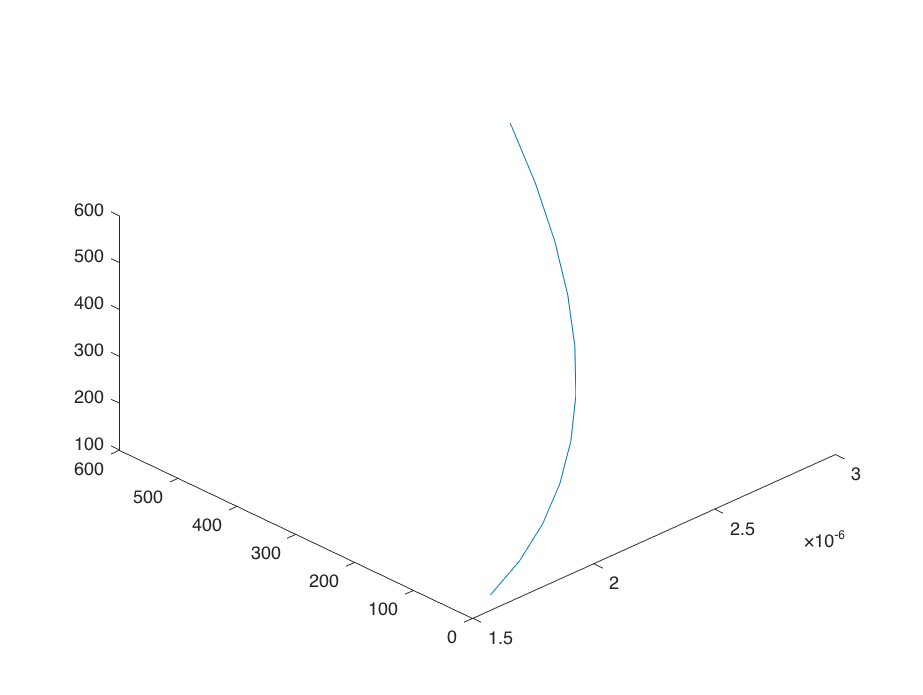

covmat=cov(table2array(database(:,2:end)));
n=length(covmat);
covmat_inv=diag(ones(1,n))/covmat;
e=sort(eig(covmat),'descend');
D=diag(e);
EC=covmat*e(:,1);EC=EC/sum(EC);
ER=mean(table2array(database(:,2:end)));ER=ER';

lambda=0:0.001:0.01;
gamma=0:0.001:0.01;
[Lambda,Gamma]=meshgrid(lambda,gamma);
X=zeros(size(Lambda));
Y=zeros(size(Lambda));
Z=zeros(size(Lambda));
for i=1:length(lambda)
    for j=1:length(lambda)
        alpha_lambda=Lambda(i,j)*ones(1,n)*covmat_inv*ER;
        alpha_gamma=-Gamma(i,j)*ones(1,n)*covmat_inv*EC;
        a1=ER'*covmat_inv*ER/sum(covmat_inv*ER);
        a2=sum(covmat_inv*ER)/sum(sum(covmat_inv));
        a3=ER'*covmat_inv*EC/sum(covmat_inv*ER);
        b1=EC'*covmat_inv*ER/sum(covmat_inv*ER);
        b2=sum(covmat_inv*EC)/sum(sum(covmat_inv));
        b3=EC'*covmat_inv*EC/sum(covmat_inv*ER);
        c=1/sum(covmat_inv*ER);
        d=a3/sum(covmat_inv*ER);
        Z(i,j)=ER'*covmat_inv*ones(n,1)+alpha_lambda*(a1-a2)+alpha_gamma*(a1-a3);
        X(i,j)=EC'*covmat_inv*ones(n,1)+alpha_lambda*(b1-b2)+alpha_gamma*(b1-b3);
        Y(i,j)=alpha_lambda^2*(a1-3*c)+alpha_gamma^2*(b3-3*c)+alpha_lambda*alpha_gamma*(d-4*c)...
            -alpha_lambda*c-alpha_gamma*c+c;
    end
end
XX=reshape(X,numel(X),1);
YY=reshape(Y,numel(X),1);
ZZ=reshape(Z,numel(X),1);
figure;
plot3(XX,YY,ZZ);

T=array2table(XX);


\begin{tabular}{l}
XX \\ 
\hline 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.5718e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.7054e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.8391e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
1.9727e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.1064e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\ 
2.24e-06 \\